## Phase 2

# Part 1

Here's the circuit designed in phase 1 of the project.

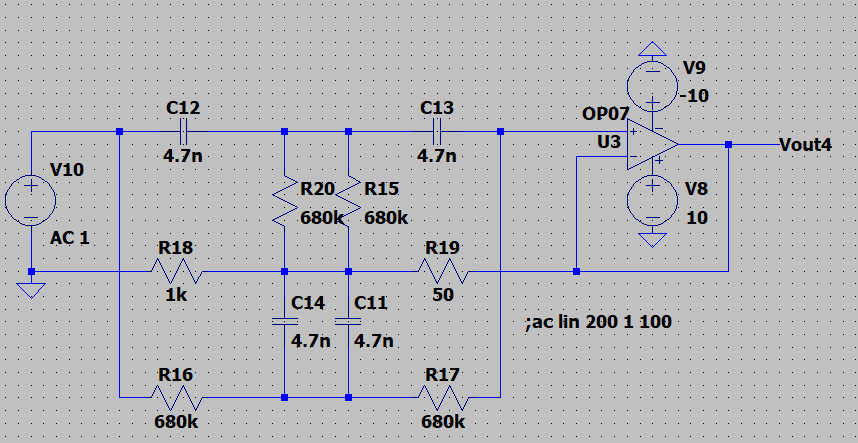

and this is the twin-t notch filter provided in the project document.

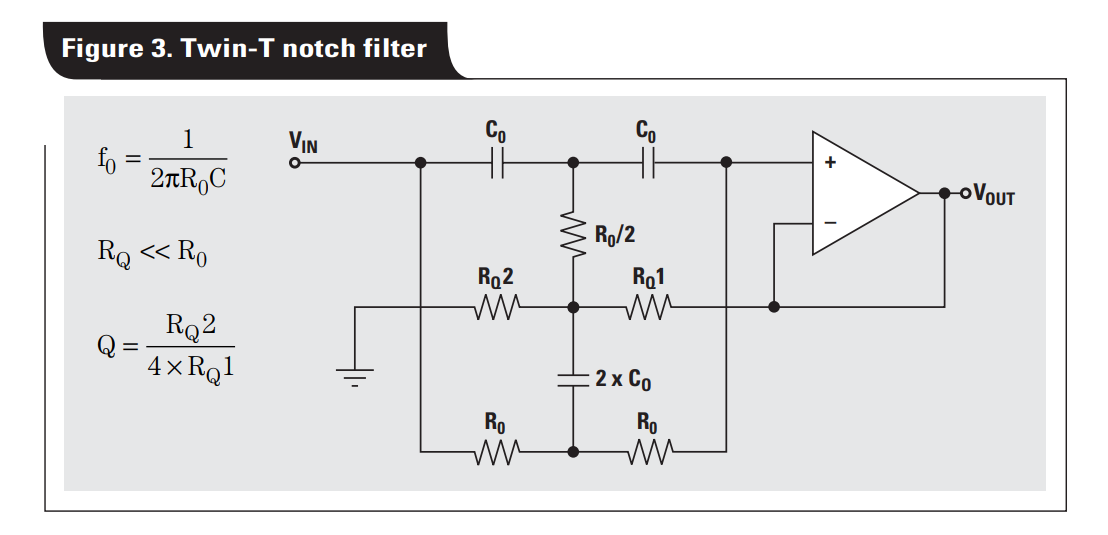

we calculate the transfer function in the two following ways.

### 1. Taking C0 and R0 as parameters (with set RQ1 and RQ2)

we write the circuit equations using node analysis method. And we calculate the transfer function. and we plot the bode diagram

% Define symbolic variables
syms V1 V2 V3 C0 R0 Vin Vout s

% Numeric values for components
RQ1 = 50;
RQ2 = 1e3;
R0_half = R0 / 2;  % Define R0/2 separately
Z_C0 = 1 / (s * C0);
Z_2C0 = 1 / (s * C0 * 2);

% Define the system of equations
eq1 = 0 == (V1 - Vin) / Z_C0 + (V1 - Vout) / Z_C0 + (V1 - V2) / R0_half;
eq2 = 0 == (Vout - V1) / Z_C0 + (Vout - V3) / R0;
eq3 = 0 == (V2 - V1) / R0_half + V2 / RQ2 + (V2 - Vout) / RQ1 + (V2 - V3) / Z_2C0;
eq4 = 0 == (V3 - Vin) / R0 + (V3 - V2) / Z_2C0 + (V3 - Vout) / R0;

% Solve the system of equations for Vout and Vin
sol = solve([eq1, eq2, eq3, eq4], [Vout, V1, V2, V3], 'ReturnConditions', true);

% Extract Vout in terms of Vin
Vout_sol = sol.Vout;

% Compute the transfer function H(s) = Vout / Vin
H_sol = simplify(Vout_sol / Vin);

% Display the transfer function
disp('H(s) = Vout / Vin is:');

H(s) = Vout / Vin is:


disp(H_sol);

$$\frac{21\,{C_{0}}^{2}\,{R_{0}}^{2}\,s^{2}+4000\,{C_{0}}^{2}\,R_{0}\,s^{2}+4000\,C_{0}\,s+21}{21\,{C_{0}}^{2}\,{R_{0}}^{2}\,s^{2}+4000\,{C_{0}}^{2}\,R_{0}\,s^{2}+4\,C_{0}\,R_{0}\,s+4000\,C_{0}\,s+21}$$

Now plotting the bode diagram

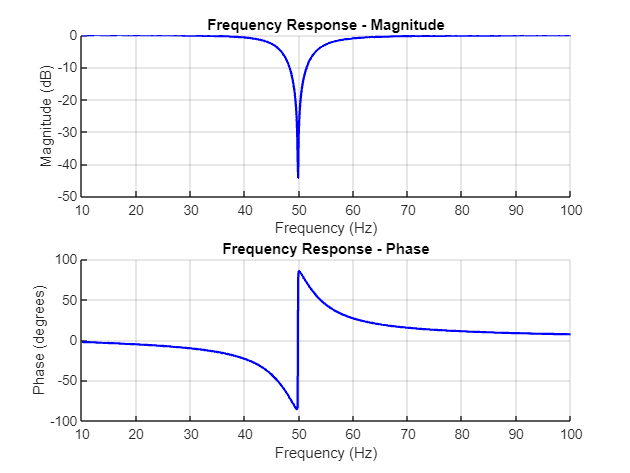

% Frequency range for response plot (10 Hz to 100 Hz)
freq = linspace(10, 100, 1000);  % 1000 points between 10 and 100 Hz
omega = 2 * pi * freq;           % Angular frequency

% Mean and standard deviation for R0 and C0
R0_mean = 680e3;  % 680k ohm
C0_mean = 4.7e-9; % 4.7 nF

% Preallocate space for transfer function results
H_all = zeros(1, length(freq));
Phase_all = zeros(1, length(freq));  % For storing the phase values

H_sample = zeros(1, length(freq));  % Preallocate for this iteration
for j = 1:length(freq)
    % Substitute nominal R0 and C0 values and s = jω (frequency)
    H_sample(j) = double(subs(H_sol, [R0, C0, s], [R0_mean, C0_mean, 1j * omega(j)]));
end

% Store the magnitude and phase of the transfer function
H_all(1, :) = abs(H_sample);
Phase_all(1, :) = angle(H_sample);  % Compute the phase for each frequency


% Plot the magnitude frequency response
figure;
subplot(2, 1, 1);  % Magnitude plot
hold on;
plot(freq, 20 * log10(mean(H_all, 1)), 'b', 'LineWidth', 1.5);  % Average response
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response - Magnitude');
grid on;
hold off;

% Plot the phase frequency response
subplot(2, 1, 2);  % Phase plot
hold on;
plot(freq, rad2deg(mean(Phase_all, 1)), 'b', 'LineWidth', 1.5);  % Average phase
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
title('Frequency Response - Phase');
grid on;
hold off;

### 2. Taking each element as a variable

As it's easier in matlab to work with matrices, instead of writing the equations and using "solve" function we use matrices.

% Define symbolic variables
syms Vin s R1 R2 R3 R4 R5 R6 C1 C2 C3 C4 Vout V1 V2 V3 real

% Define admittances for resistors (Y = 1/R)
Y1 = 1 / R1;
Y2 = 1 / R2;
Y3 = 1 / R3;
Y4 = 1 / R4;
Y5 = 1 / R5;
Y6 = 1 / R6;

% Define admittances for capacitors (Y = s * C)
Y_C1 = s * C1;
Y_C2 = s * C2;
Y_C3 = s * C3;
Y_C4 = s * C4;

% Admittance matrix (Y matrix)
Y_matrix = [
    -Y_C4,               Y_C1 + Y1 + Y2 + Y_C4, -Y1 - Y2,               0;
    Y_C4 + Y6,          -Y_C4,                  0,                     -Y6;
    -Y3,                -Y1 - Y2,               (Y_C2 + Y_C3) + Y1 + Y2 + Y3 + Y4, -(Y_C2 + Y_C3);
    -Y6,                0,                     -(Y_C2 + Y_C3),         Y5 + Y6 + (Y_C2 + Y_C3)
];

% Input current vector (I vector)
I_vector = [Vin * Y_C1; 0; 0; Vin * Y5];

% Solve the system of equations Y * V = I
V = Y_matrix \ I_vector;  % Solve for node voltages

% Extract Vout (first element of V)
Vout_sol = V(1);

% Compute the transfer function H(s) = Vout / Vin
H_sol = simplify(Vout_sol / Vin);

% Display the symbolic transfer function
% disp('H(s) = Vout / Vin is:');
 disp(H_sol);

Since the equations are basically the same we go straight to monte-carlo simulation.

## Monte-Carlo simulation

### - 2% tolerance for all elements (with R3 and R4 being ideal )

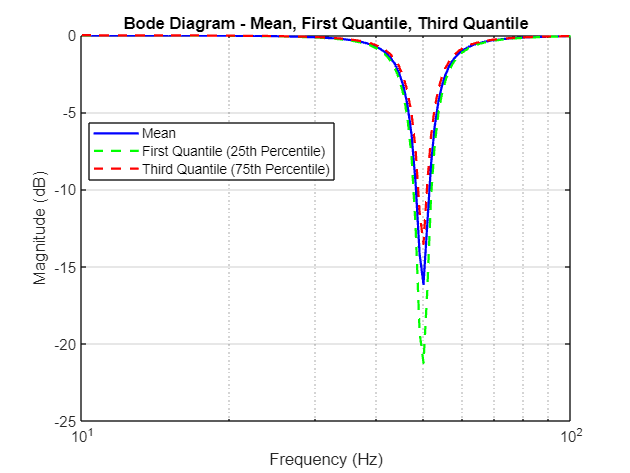

 % Number of Monte Carlo iterations
numIterations = 10000;

% Frequency range for response plot (10 Hz to 100 kHz)
f = linspace(10, 100, 100);  % 100 points between 10 Hz and 100 Hz
omega = 2 * pi * f;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 50;   % 50 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

% Tolerance (2%)
tolerance = 0.02;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% Monte Carlo simulation
for i = 1:numIterations
    % Generate random values for resistors and capacitors using normrnd
    R1_rand = normrnd(R1_val, tolerance * R1_val);
    R2_rand = normrnd(R2_val, tolerance * R2_val);
    R5_rand = normrnd(R5_val, tolerance * R5_val);
    R6_rand = normrnd(R6_val, tolerance * R6_val);
    C1_rand = normrnd(C1_val, tolerance * C1_val);
    C2_rand = normrnd(C2_val, tolerance * C2_val);
    C3_rand = normrnd(C3_val, tolerance * C3_val);
    C4_rand = normrnd(C4_val, tolerance * C4_val);
    
    % Substitute all random values including constants R3 and R4
    H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
        [R1_rand, R2_rand, R3_val, R4_val, R5_rand, R6_rand, C1_rand, C2_rand, C3_rand, C4_rand]);
    
    % Convert symbolic transfer function to numeric function with s as the only variable
    H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
    
    % Compute magnitude response
    H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
end

% Compute mean, first quantile, and third quantile of H_mag_all
H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response
H_mag_first_quantile = quantile(H_mag_all, 0.25, 1);  % 25th percentile (first quantile)
H_mag_third_quantile = quantile(H_mag_all, 0.75, 1);  % 75th percentile (third quantile)

% Convert to decibels (dB)
H_mag_mean_dB = 20 * log10(H_mag_mean);
H_mag_first_quantile_dB = 20 * log10(H_mag_first_quantile);
H_mag_third_quantile_dB = 20 * log10(H_mag_third_quantile);

% Plot Bode diagram
figure;
semilogx(f, H_mag_mean_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, H_mag_first_quantile_dB, '--g', 'LineWidth', 1.5);
semilogx(f, H_mag_third_quantile_dB, '--r', 'LineWidth', 1.5);
grid on;

% Add labels, title, and legend
title('Bode Diagram - Mean, First Quantile, Third Quantile');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Mean', 'First Quantile (25th Percentile)', 'Third Quantile (75th Percentile)', 'Location', 'Best');
hold off;

since linspace has 50Hz, it will be the closest to our target frequency. so we plot the histogram at 50Hz.

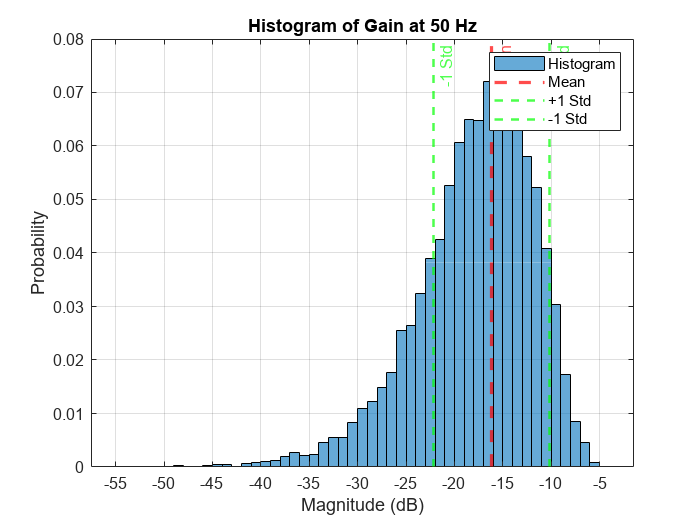

% Target frequency fo (Hz)
fo_target = 50.0;  % Target frequency is 49.8 Hz

% Find the closest index to fo_target in the frequency array
[~, fo_index] = min(abs(f - fo_target));

% Extract the mean magnitude response at fo
H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

% Extract all Monte Carlo responses at fo for histogram comparison
H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

% Compute standard deviation at fo
std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

% Plot the histogram of all Monte Carlo responses
figure;
histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
hold on;

% Plot a vertical line for the mean value
xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

% Plot vertical lines for ±1 standard deviation
xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

% Labels, title, and grid
xlabel('Magnitude (dB)');
ylabel('Probability');
title(['Histogram of Gain at ', num2str(fo_target), ' Hz']);
grid on;
legend('Histogram', 'Mean', '+1 Std', '-1 Std');
hold off;

### 5% tolerance for each single element (others being ideal)

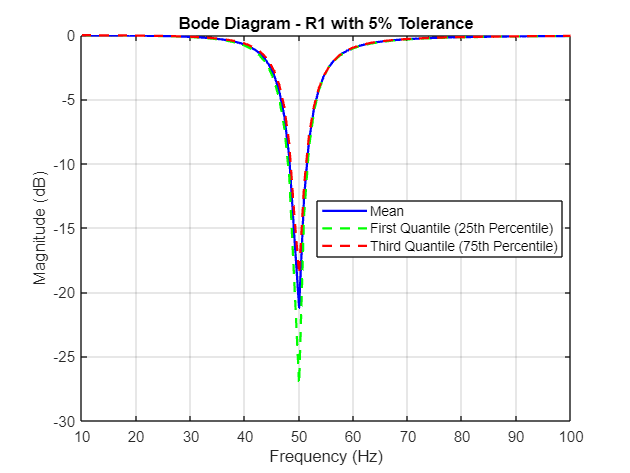

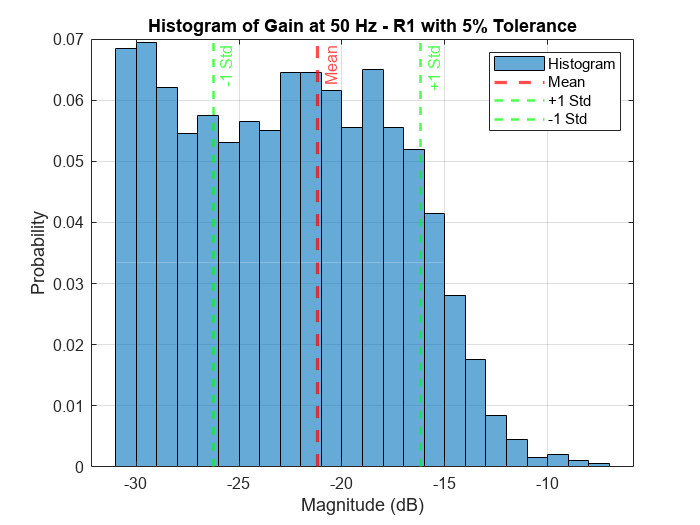

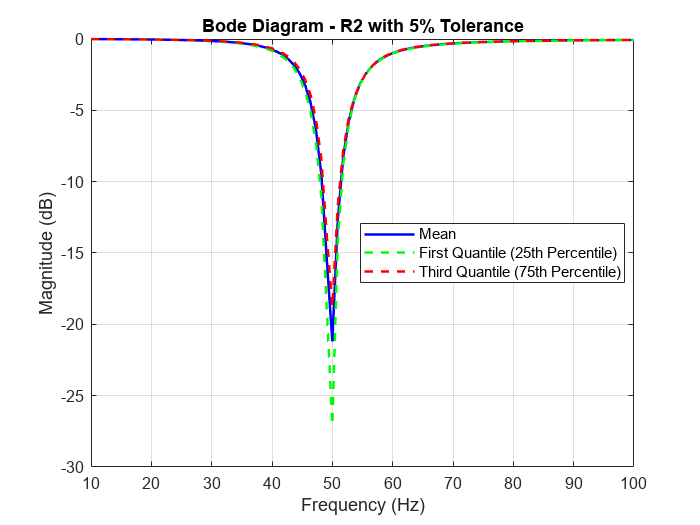

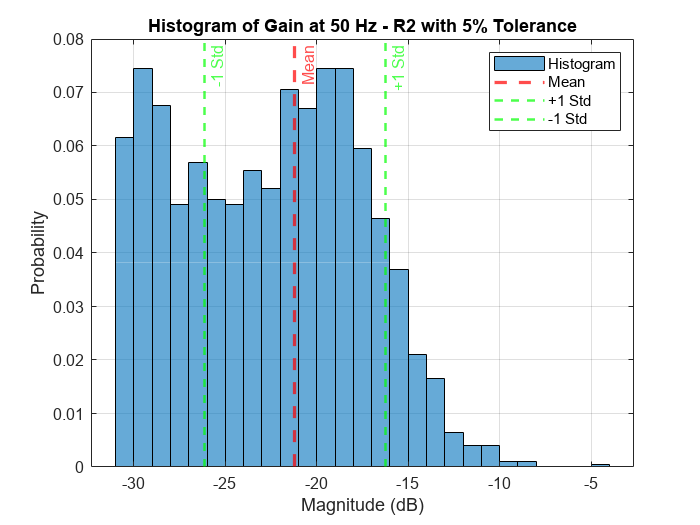

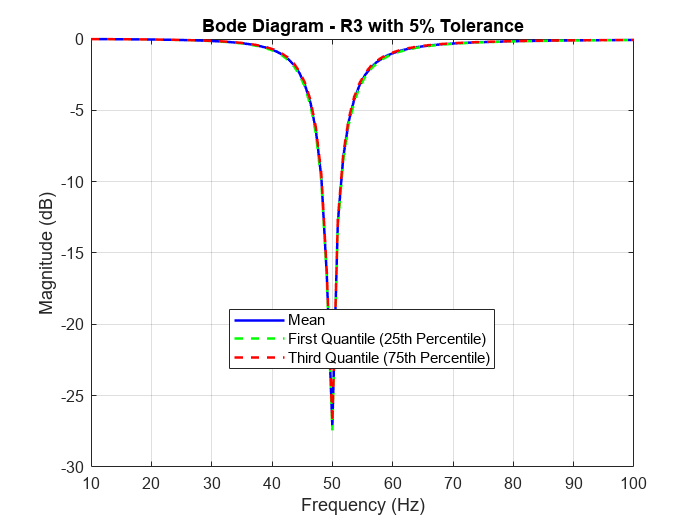

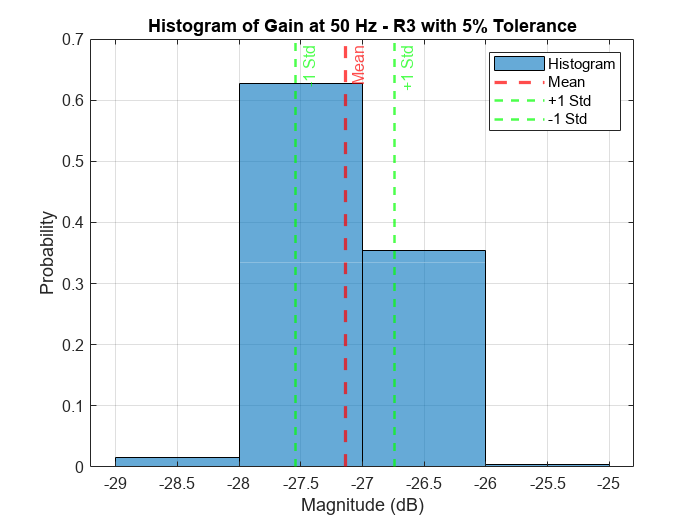

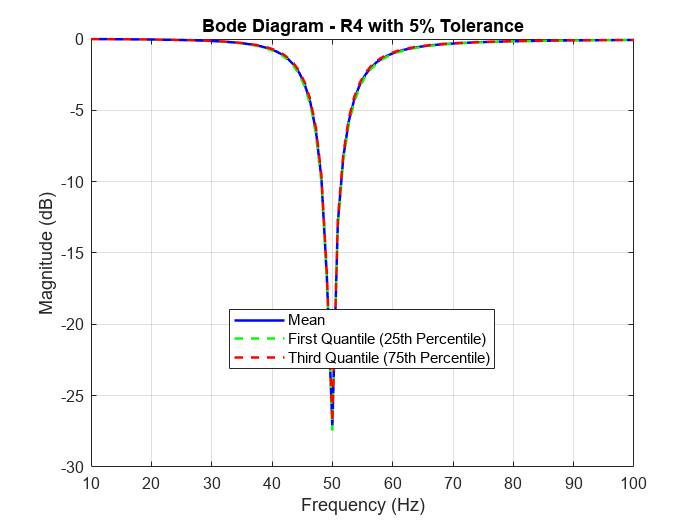

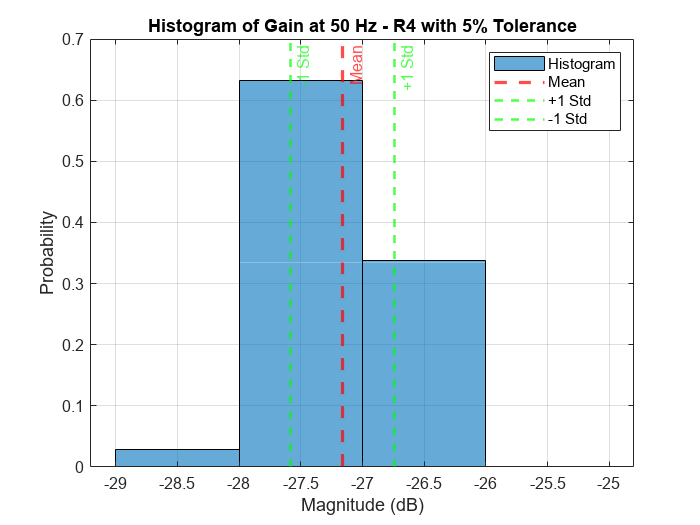

% Number of Monte Carlo iterations
numIterations = 2000;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 50;   % 50 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

% Tolerance (5%)
tolerance = 0.05;

% Frequency range for response plot (10 Hz to 100 kHz)
f = linspace(10, 100, 100);  % 100 points between 10 Hz and 100 kHz
omega = 2 * pi * f;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% List of components to apply tolerance to
components = {'R1', 'R2', 'R3', 'R4', 'R5', 'R6', 'C1', 'C2', 'C3', 'C4'};

% Loop through each component and apply 5% tolerance
for k = 1:length(components)
    % Apply 5% tolerance to the current component, others remain ideal
    for i = 1:numIterations
        % Generate random values for the current component
        switch components{k}
            case 'R1'
                R1_rand = normrnd(R1_val, tolerance * R1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_rand, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R2'
                R2_rand = normrnd(R2_val, tolerance * R2_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_rand, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R3'
                R3_rand = normrnd(R3_val, tolerance * R3_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_rand, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R4'
                R4_rand = normrnd(R4_val, tolerance * R4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_rand, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R5'
                R5_rand = normrnd(R5_val, tolerance * R5_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_rand, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R6'
                R6_rand = normrnd(R6_val, tolerance * R6_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_rand, C1_val, C2_val, C3_val, C4_val]);
            case 'C1'
                C1_rand = normrnd(C1_val, tolerance * C1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_rand, C2_val, C3_val, C4_val]);
            case 'C2'
                C2_rand = normrnd(C2_val, tolerance * C2_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_rand, C3_val, C4_val]);
            case 'C3'
                C3_rand = normrnd(C3_val, tolerance * C3_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_rand, C4_val]);
            case 'C4'
                C4_rand = normrnd(C4_val, tolerance * C4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_rand]);
        end
        
        % Convert symbolic transfer function to numeric function with s as the only variable
        H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
        
        % Compute magnitude response
        H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
    end

    % Compute mean, first quantile, and third quantile of H_mag_all
    H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response
    H_mag_first_quantile = quantile(H_mag_all, 0.25, 1);  % 25th percentile (first quantile)
    H_mag_third_quantile = quantile(H_mag_all, 0.75, 1);  % 75th percentile (third quantile)

    % Convert to decibels (dB)
    H_mag_mean_dB = 20 * log10(H_mag_mean);
    H_mag_first_quantile_dB = 20 * log10(H_mag_first_quantile);
    H_mag_third_quantile_dB = 20 * log10(H_mag_third_quantile);


    % Target frequency for fo (Hz)
    fo_target = 50.0;  % Target frequency is 49.8 Hz

    % Find the closest index to fo_target in the frequency array
    [~, fo_index] = min(abs(f - fo_target));

    % Extract the mean magnitude response at fo
    H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
    H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

    % Extract all Monte Carlo responses at fo for histogram comparison
    H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

    % Compute standard deviation at fo
    std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

    % Plot the histogram of all Monte Carlo responses
    figure;
    histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
    hold on;

    % Plot a vertical line for the mean value
    xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

    % Plot vertical lines for ±1 standard deviation
    xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

    % Labels, title, and grid
    xlabel('Magnitude (dB)');
    ylabel('Probability');
    title(['Histogram of Gain at ', num2str(fo_target), ' Hz - ', components{k} ' with 5% Tolerance']);
    grid on;
    legend('Histogram', 'Mean', '+1 Std', '-1 Std');
    hold off;
end

## Improving the circuit

given the results above we that the target frequency response of P(Gain at 50Hz < -20dB) > 0.9 is rarely achieved. There are mutiple ways to bridge this gap. We can:

- use elements with lower tolerances.

- lower the Q

- use a second filter

of the options the first one is not feasible because elements with lower tolerances either can't be found in the country or are extremely expensive. Since our task is to design a single filter the third option is also not a good option. So our last resort is to decrease the Q and instead gain more insensitivity to tolerance. Here we simulate the frequency response for R3 = {130, 150, 180}.

#### R3 = 130

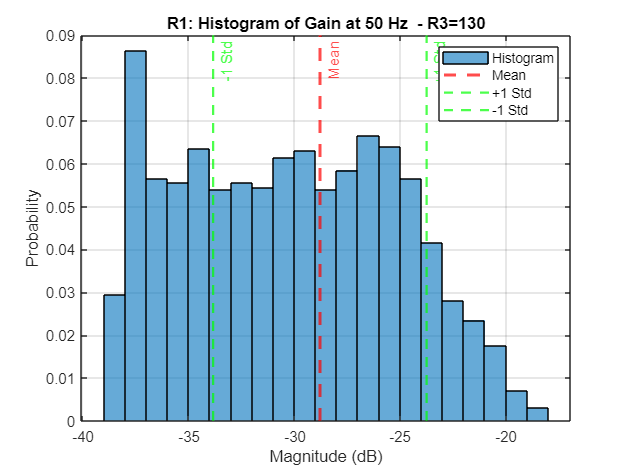

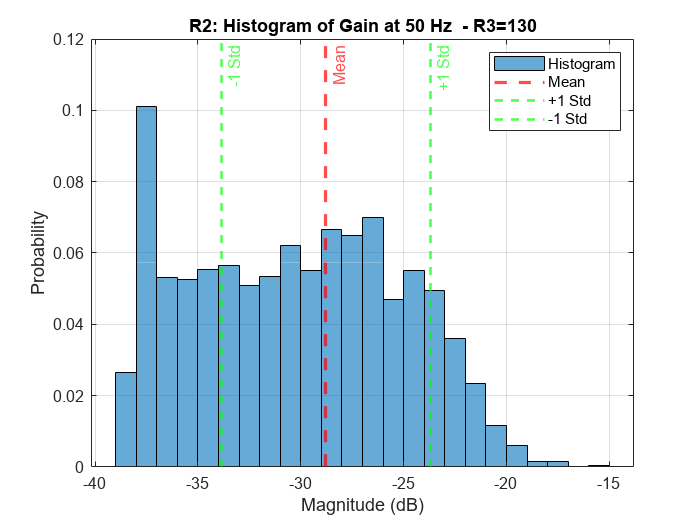

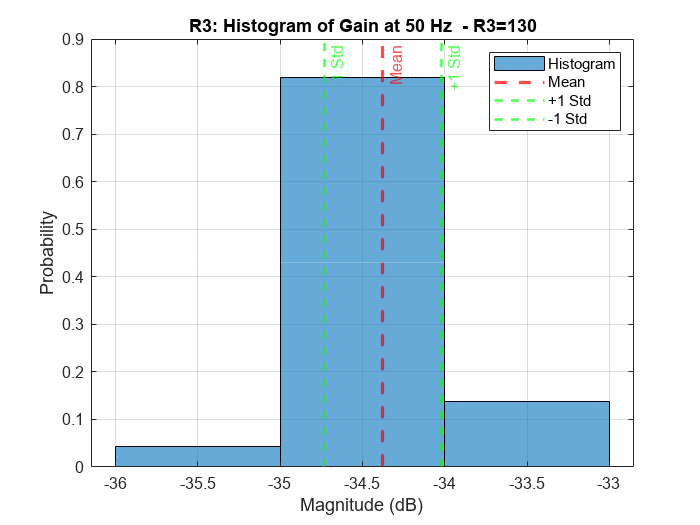

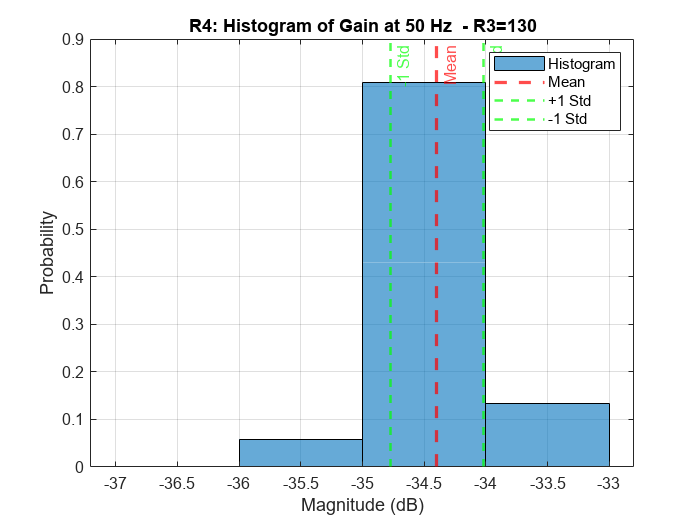

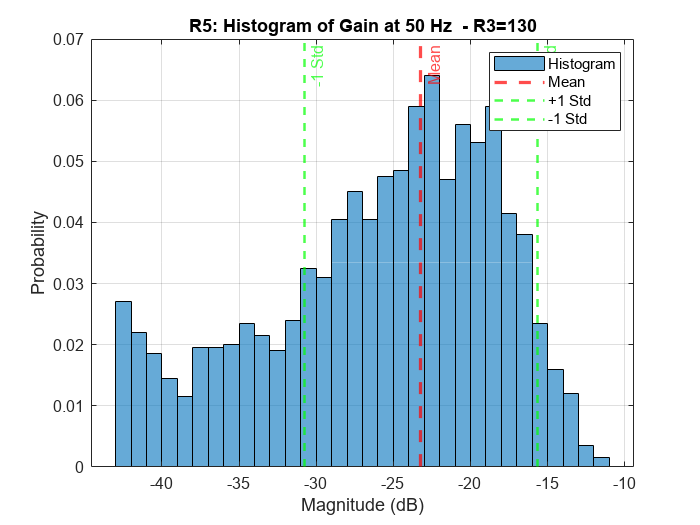

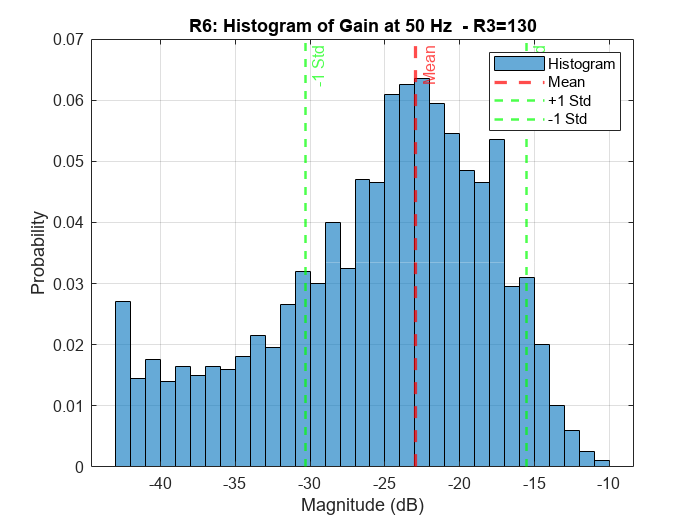

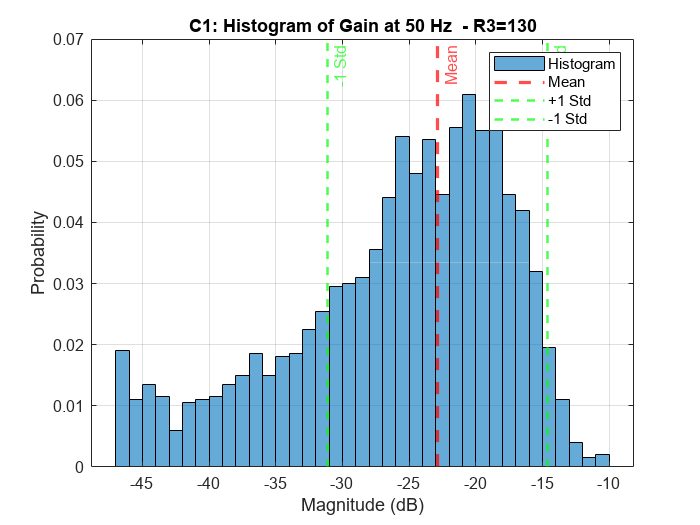

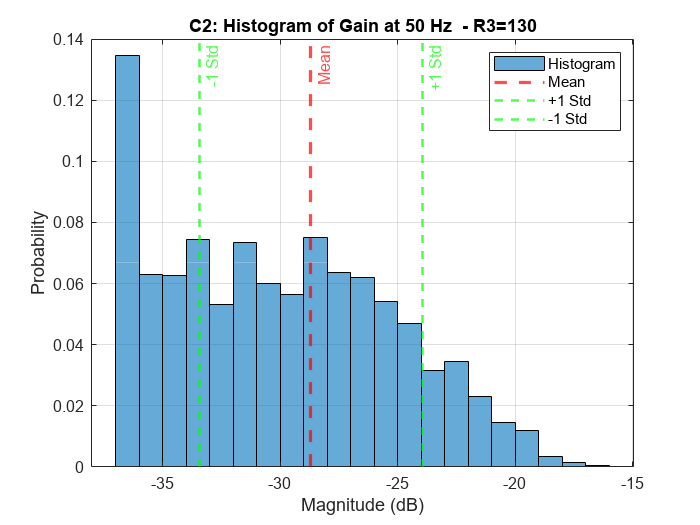

% Number of Monte Carlo iterations
numIterations = 2000;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 130;   % 130 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

tolerance = 0.05;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% List of components to apply tolerance to
components = {'R1', 'R2', 'R3', 'R4', 'R5', 'R6', 'C1', 'C2', 'C3', 'C4'};

% Loop through each component and apply 5% tolerance
for k = 1:length(components)
    % Apply 5% tolerance to the current component, others remain ideal
    for i = 1:numIterations
        % Generate random values for the current component
        switch components{k}
            case 'R1'
                R1_rand = normrnd(R1_val, tolerance * R1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_rand, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R2'
                R2_rand = normrnd(R2_val, tolerance * R2_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_rand, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R3'
                R3_rand = normrnd(R3_val, tolerance * R3_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_rand, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R4'
                R4_rand = normrnd(R4_val, tolerance * R4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_rand, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R5'
                R5_rand = normrnd(R5_val, tolerance * R5_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_rand, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R6'
                R6_rand = normrnd(R6_val, tolerance * R6_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_rand, C1_val, C2_val, C3_val, C4_val]);
            case 'C1'
                C1_rand = normrnd(C1_val, tolerance * C1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_rand, C2_val, C3_val, C4_val]);
            case 'C2'
                C2_rand = normrnd(C2_val, tolerance * C2_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_rand, C3_val, C4_val]);
            case 'C3'
                C3_rand = normrnd(C3_val, tolerance * C3_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_rand, C4_val]);
            case 'C4'
                C4_rand = normrnd(C4_val, tolerance * C4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_rand]);
        end
        
        % Convert symbolic transfer function to numeric function with s as the only variable
        H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
        
        % Compute magnitude response
        H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
    end

    % Compute mean, first quantile, and third quantile of H_mag_all
    H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response

    % Convert to decibels (dB)
    H_mag_mean_dB = 20 * log10(H_mag_mean);

    % Target frequency for fo (Hz)
    fo_target = 50.0;  % Target frequency is 49.8 Hz

    % Find the closest index to fo_target in the frequency array
    [~, fo_index] = min(abs(f - fo_target));

    % Extract the mean magnitude response at fo
    H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
    H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

    % Extract all Monte Carlo responses at fo for histogram comparison
    H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

    % Compute standard deviation at fo
    std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

    % Plot the histogram of all Monte Carlo responses
    figure;
    histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
    hold on;

    % Plot a vertical line for the mean value
    xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

    % Plot vertical lines for ±1 standard deviation
    xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

    % Labels, title, and grid
    xlabel('Magnitude (dB)');
    ylabel('Probability');
    title([num2str(components{k}), ': Histogram of Gain at ', num2str(fo_target), ' Hz ', ' - R3=', num2str(R3_val)]);
    grid on;
    legend('Histogram', 'Mean', '+1 Std', '-1 Std');
    hold off;
end

#### R3 = 150

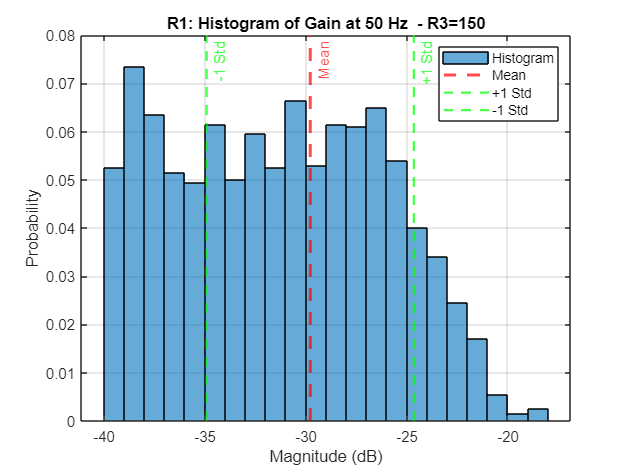

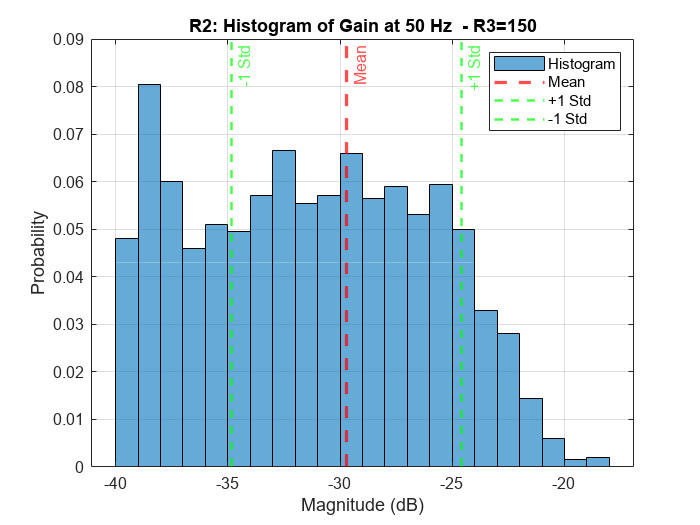

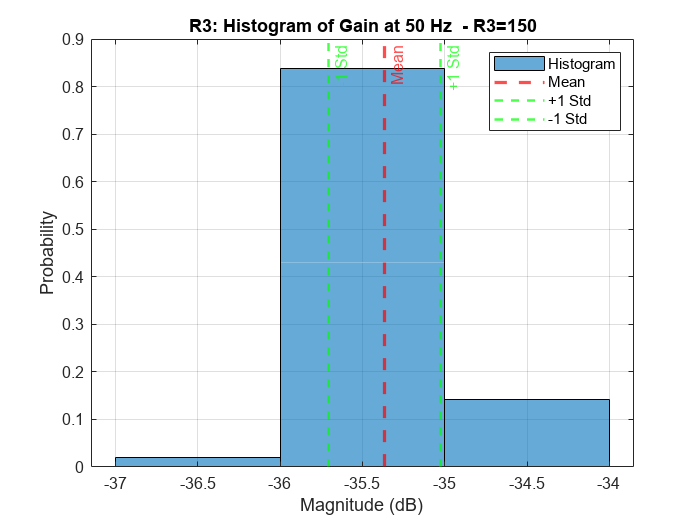

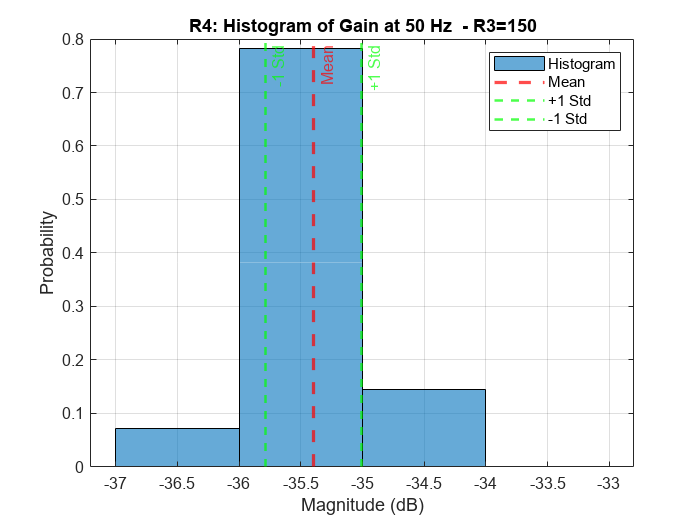

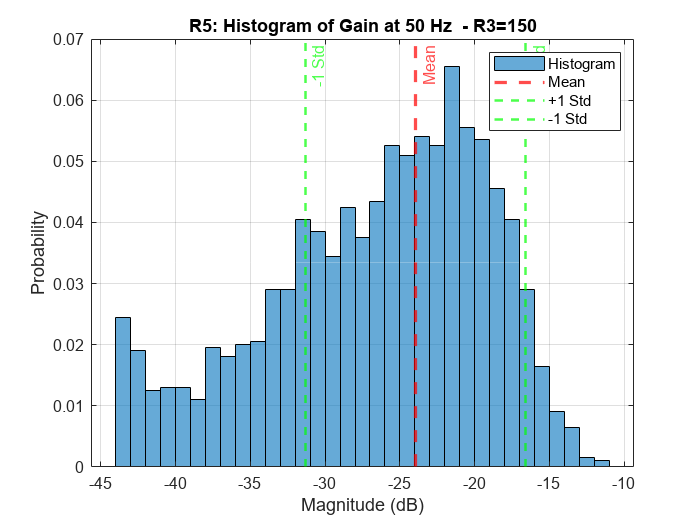

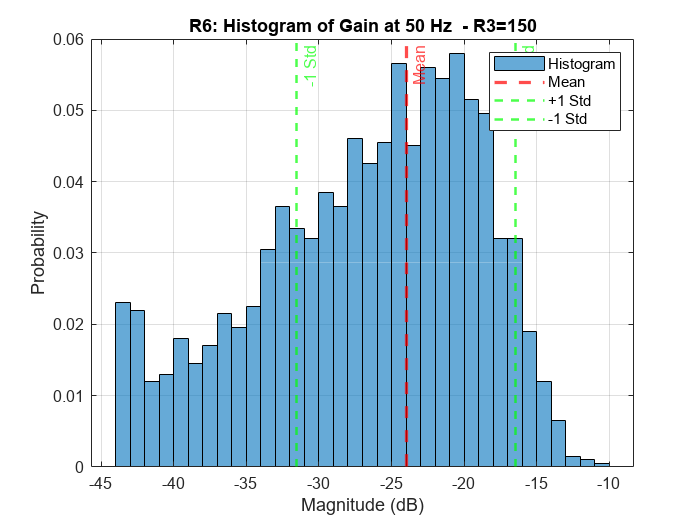

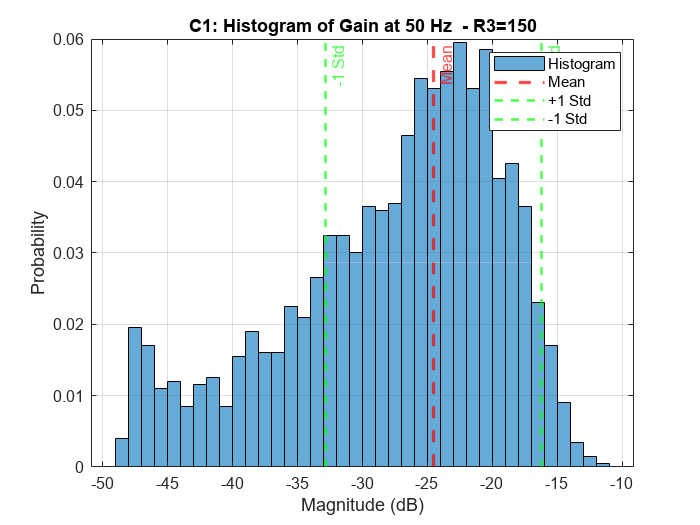

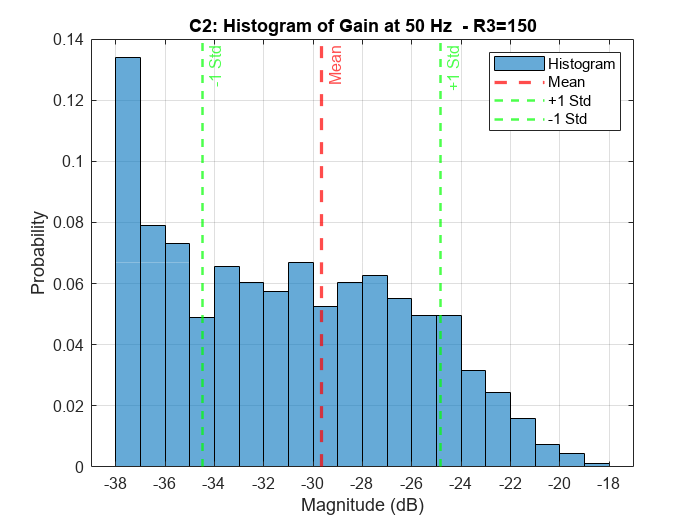

% Number of Monte Carlo iterations
numIterations = 2000;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 150;   % 150 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

tolerance = 0.05;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% List of components to apply tolerance to
components = {'R1', 'R2', 'R3', 'R4', 'R5', 'R6', 'C1', 'C2', 'C3', 'C4'};

% Loop through each component and apply 5% tolerance
for k = 1:length(components)
    % Apply 5% tolerance to the current component, others remain ideal
    for i = 1:numIterations
        % Generate random values for the current component
        switch components{k}
            case 'R1'
                R1_rand = normrnd(R1_val, tolerance * R1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_rand, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R2'
                R2_rand = normrnd(R2_val, tolerance * R2_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_rand, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R3'
                R3_rand = normrnd(R3_val, tolerance * R3_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_rand, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R4'
                R4_rand = normrnd(R4_val, tolerance * R4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_rand, R5_val, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R5'
                R5_rand = normrnd(R5_val, tolerance * R5_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_rand, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R6'
                R6_rand = normrnd(R6_val, tolerance * R6_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_rand, C1_val, C2_val, C3_val, C4_val]);
            case 'C1'
                C1_rand = normrnd(C1_val, tolerance * C1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_rand, C2_val, C3_val, C4_val]);
            case 'C2'
                C2_rand = normrnd(C2_val, tolerance * C2_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_rand, C3_val, C4_val]);
            case 'C3'
                C3_rand = normrnd(C3_val, tolerance * C3_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_rand, C4_val]);
            case 'C4'
                C4_rand = normrnd(C4_val, tolerance * C4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_rand]);
        end
        
        % Convert symbolic transfer function to numeric function with s as the only variable
        H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
        
        % Compute magnitude response
        H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
    end

    % Compute mean, first quantile, and third quantile of H_mag_all
    H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response

    % Convert to decibels (dB)
    H_mag_mean_dB = 20 * log10(H_mag_mean);

    % Target frequency for fo (Hz)
    fo_target = 50.0;  % Target frequency is 49.8 Hz

    % Find the closest index to fo_target in the frequency array
    [~, fo_index] = min(abs(f - fo_target));

    % Extract the mean magnitude response at fo
    H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
    H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

    % Extract all Monte Carlo responses at fo for histogram comparison
    H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

    % Compute standard deviation at fo
    std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

    % Plot the histogram of all Monte Carlo responses
    figure;
    histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
    hold on;

    % Plot a vertical line for the mean value
    xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

    % Plot vertical lines for ±1 standard deviation
    xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

    % Labels, title, and grid
    xlabel('Magnitude (dB)');
    ylabel('Probability');
    title([num2str(components{k}), ': Histogram of Gain at ', num2str(fo_target), ' Hz ', ' - R3=', num2str(R3_val)]);
    grid on;
    legend('Histogram', 'Mean', '+1 Std', '-1 Std');
    hold off;
end

Now given the simulation above we look at the -3dB bandwidth to determine which one is better.

For R3 = 130, it's about 23Hz.

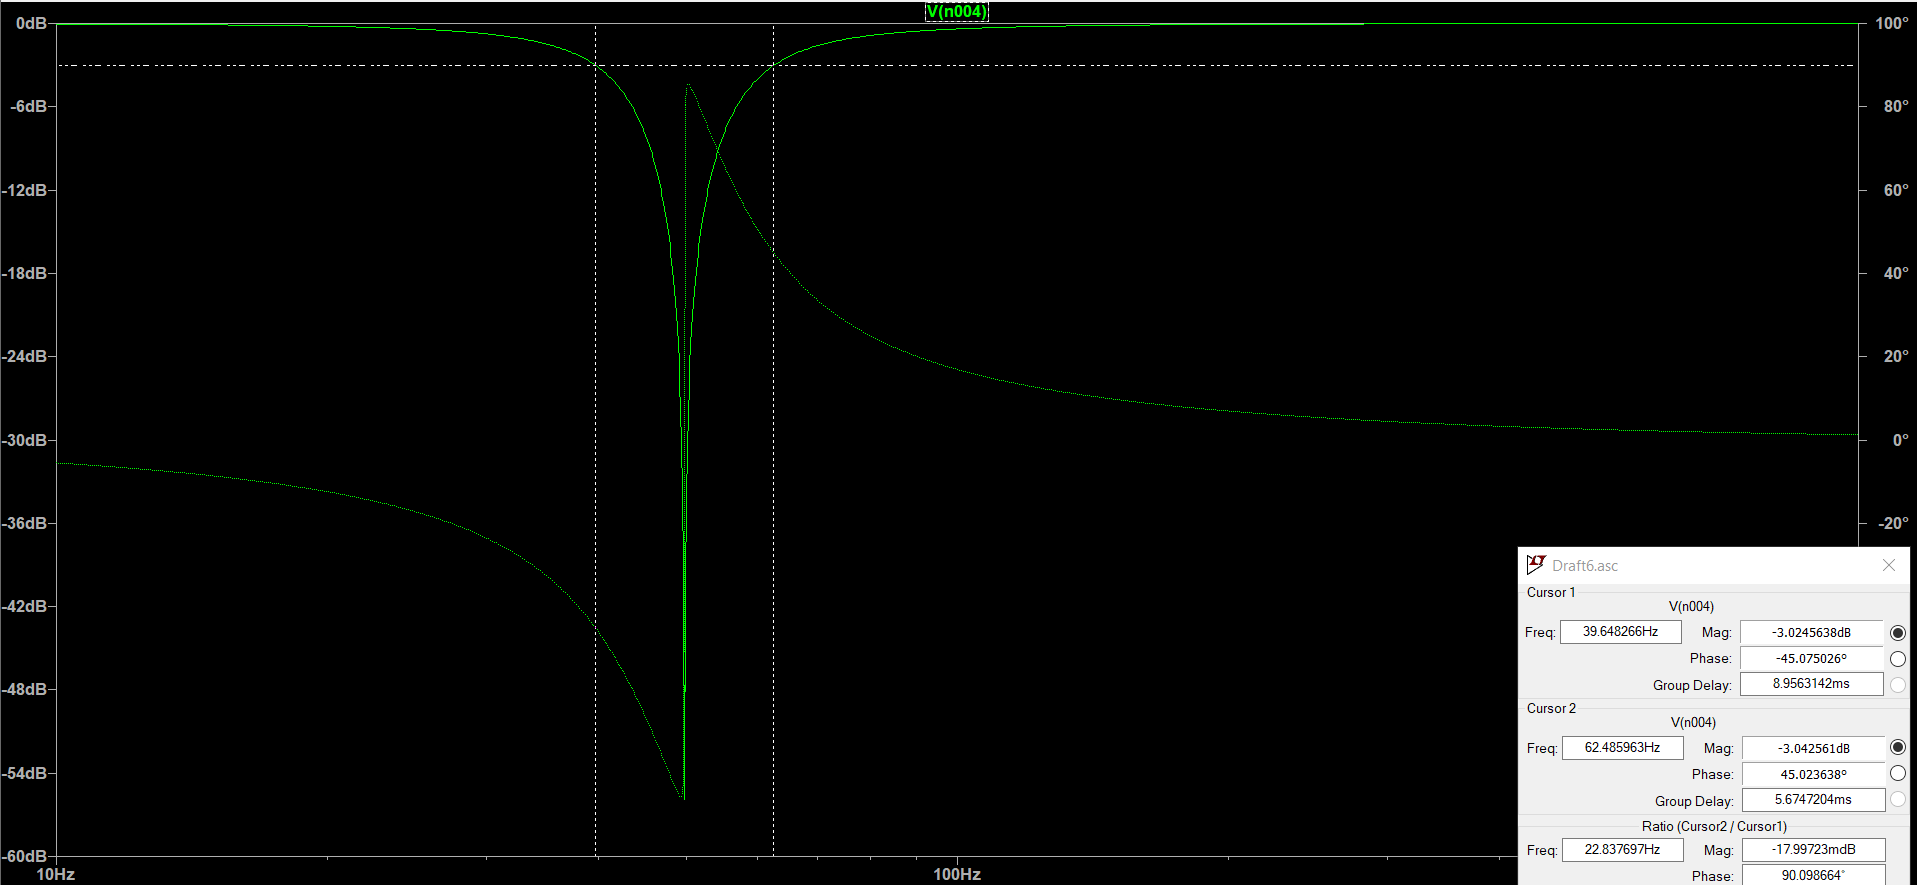

For R3 = 150, it's about 26Hz.

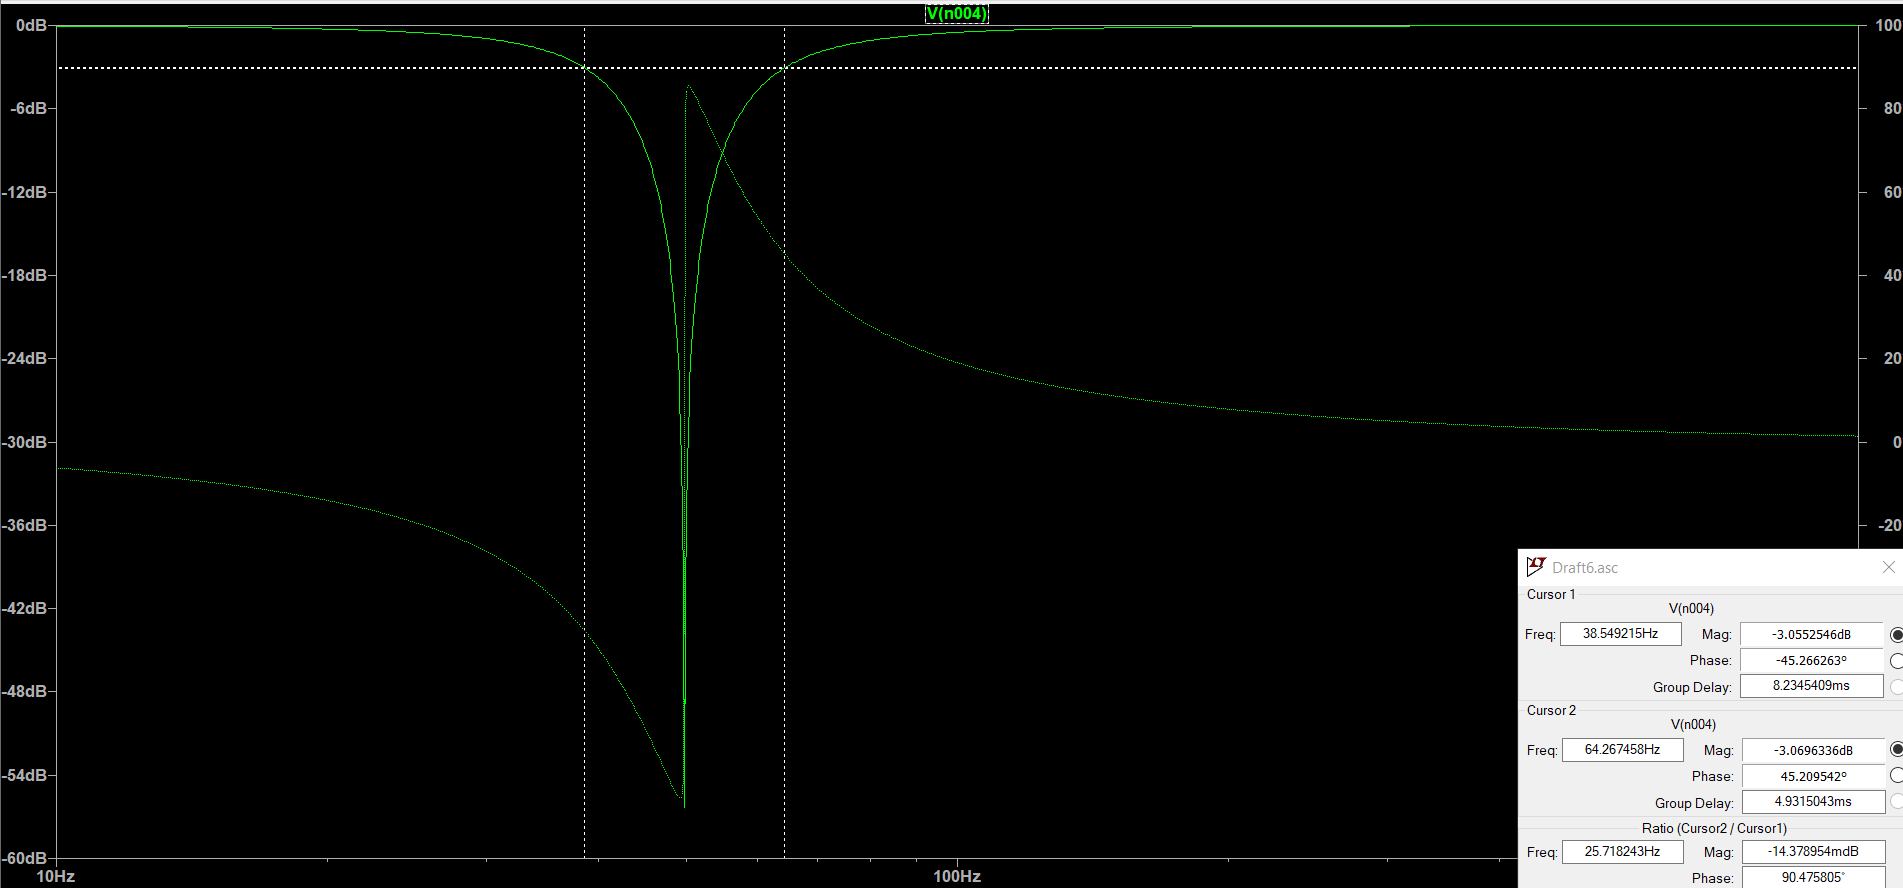

## Finding the maximum tolerance for each element (R3 = 150)

when looking at the graphs with R3 = 150, we realize that not all of our elements met the requirement P(Gain at 50Hz < -20dB) > 0.9. For the ones that did, we can say that 5% tolerance will suffice and for the ones that didn't we now run a new simulation with 2% tolerance to see if it will suffice (2% because it's the next common tolerance after 5%). It's worth mentioning that the results weren't that far off and the accuracies given 5% tolerance was about 0.85.

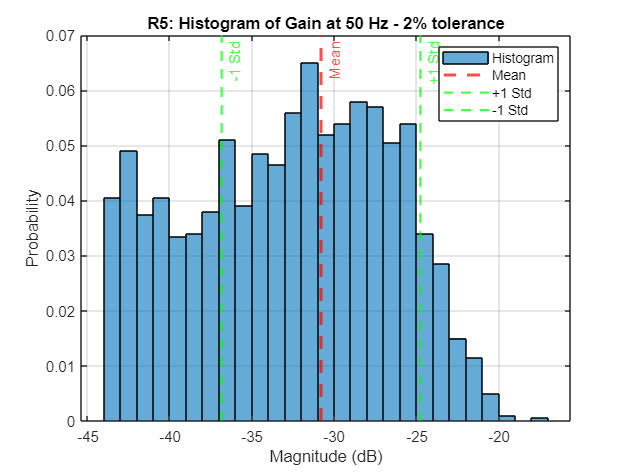

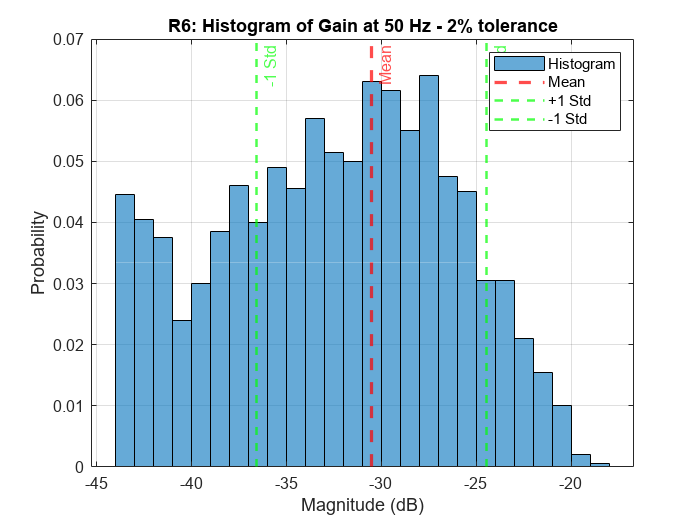

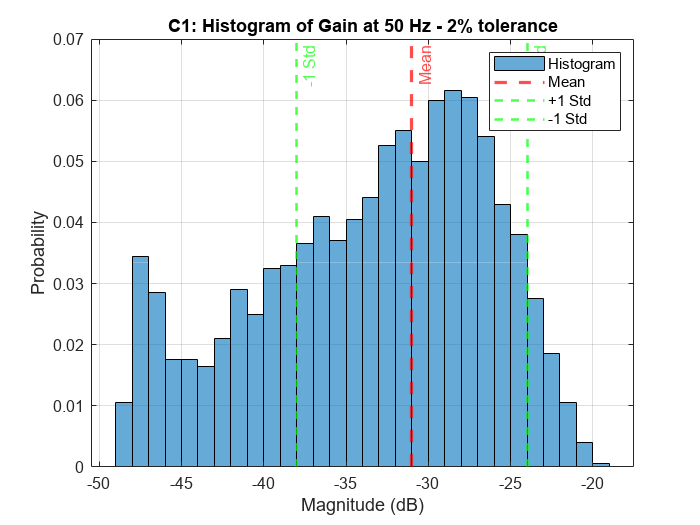

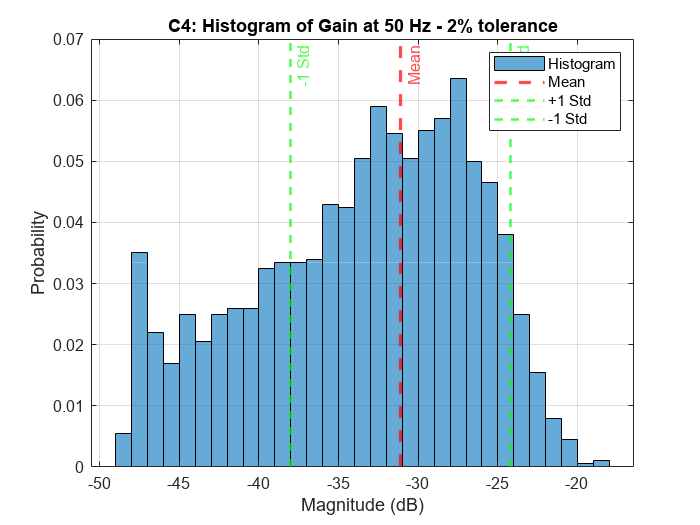

% Number of Monte Carlo iterations
numIterations = 2000;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 150;   % 150 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

tolerance = 0.02;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% List of components to apply tolerance to
components = {'R5', 'R6', 'C1', 'C4'};

% Loop through each component and apply 5% tolerance
for k = 1:length(components)
    % Apply 5% tolerance to the current component, others remain ideal
    for i = 1:numIterations
        % Generate random values for the current component
        switch components{k}
            case 'R5'
                R5_rand = normrnd(R5_val, tolerance * R5_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_rand, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R6'
                R6_rand = normrnd(R6_val, tolerance * R6_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_rand, C1_val, C2_val, C3_val, C4_val]);
            case 'C1'
                C1_rand = normrnd(C1_val, tolerance * C1_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_rand, C2_val, C3_val, C4_val]);
            case 'C4'
                C4_rand = normrnd(C4_val, tolerance * C4_val);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_rand]);
        end
        
        % Convert symbolic transfer function to numeric function with s as the only variable
        H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
        
        % Compute magnitude response
        H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
    end

    % Compute mean, first quantile, and third quantile of H_mag_all
    H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response

    % Convert to decibels (dB)
    H_mag_mean_dB = 20 * log10(H_mag_mean);

    % Target frequency for fo (Hz)
    fo_target = 50.0;  % Target frequency is 49.8 Hz

    % Find the closest index to fo_target in the frequency array
    [~, fo_index] = min(abs(f - fo_target));

    % Extract the mean magnitude response at fo
    H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
    H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

    % Extract all Monte Carlo responses at fo for histogram comparison
    H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

    % Compute standard deviation at fo
    std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

    % Plot the histogram of all Monte Carlo responses
    figure;
    histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
    hold on;

    % Plot a vertical line for the mean value
    xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

    % Plot vertical lines for ±1 standard deviation
    xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

    % Labels, title, and grid
    xlabel('Magnitude (dB)');
    ylabel('Probability');
    title([num2str(components{k}), ': Histogram of Gain at ', num2str(fo_target), ' Hz - 2% tolerance']);
    grid on;
    legend('Histogram', 'Mean', '+1 Std', '-1 Std');
    hold off;
end

Now we see that with 2% tolerance for R5, R6, C1 and C4 the set criteria is met. so the max tolerance for these elements would be 2%.

### Final circuit response with calculated tolerances

setting the tolerances we calculated for each element, we plot histogram chart of the final circuit.

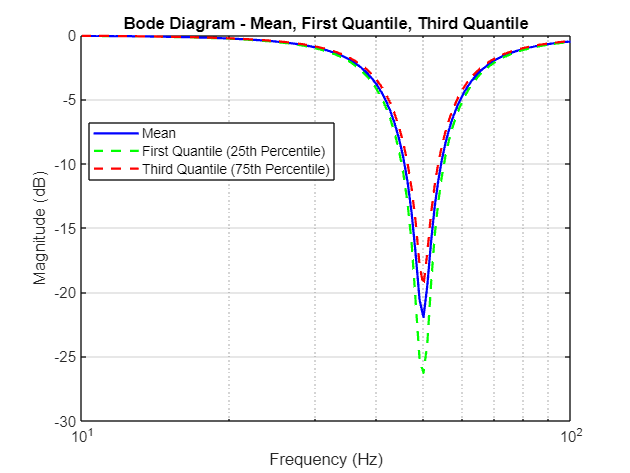

% Number of Monte Carlo iterations
numIterations = 2000;

% Frequency range for response plot (10 Hz to 100 kHz)
f = linspace(10, 100, 100);  % 100 points between 10 Hz and 100 Hz
omega = 2 * pi * f;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 150;   % 150 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

% Tolerance (2% and 5%)
tolerance_low = 0.02;
tolerance = 0.05;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% Monte Carlo simulation
for i = 1:numIterations
    % Generate random values for resistors and capacitors using normrnd
    R1_rand = normrnd(R1_val, tolerance * R1_val);
    R2_rand = normrnd(R2_val, tolerance * R2_val);
    R3_rand = normrnd(R3_val, tolerance * R3_val);
    R4_rand = normrnd(R4_val, tolerance * R4_val);
    R5_rand = normrnd(R5_val, tolerance_low * R5_val);
    R6_rand = normrnd(R6_val, tolerance_low * R6_val);
    C1_rand = normrnd(C1_val, tolerance_low * C1_val);
    C2_rand = normrnd(C2_val, tolerance * C2_val);
    C3_rand = normrnd(C3_val, tolerance * C3_val);
    C4_rand = normrnd(C4_val, tolerance_low * C4_val);
    
    % Substitute all random values including constants R3 and R4
    H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
        [R1_rand, R2_rand, R3_val, R4_val, R5_rand, R6_rand, C1_rand, C2_rand, C3_rand, C4_rand]);
    
    % Convert symbolic transfer function to numeric function with s as the only variable
    H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
    
    % Compute magnitude response
    H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
end

% Compute mean, first quantile, and third quantile of H_mag_all
H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response
H_mag_first_quantile = quantile(H_mag_all, 0.25, 1);  % 25th percentile (first quantile)
H_mag_third_quantile = quantile(H_mag_all, 0.75, 1);  % 75th percentile (third quantile)

% Convert to decibels (dB)
H_mag_mean_dB = 20 * log10(H_mag_mean);
H_mag_first_quantile_dB = 20 * log10(H_mag_first_quantile);
H_mag_third_quantile_dB = 20 * log10(H_mag_third_quantile);

% Plot Bode diagram
figure;
semilogx(f, H_mag_mean_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, H_mag_first_quantile_dB, '--g', 'LineWidth', 1.5);
semilogx(f, H_mag_third_quantile_dB, '--r', 'LineWidth', 1.5);
grid on;

% Add labels, title, and legend
title('Bode Diagram - Mean, First Quantile, Third Quantile');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Mean', 'First Quantile (25th Percentile)', 'Third Quantile (75th Percentile)', 'Location', 'Best');
hold off;

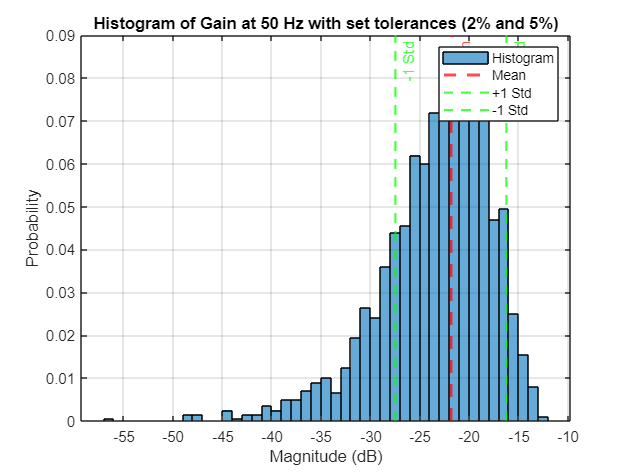

% Target frequency fo (Hz)
fo_target = 50.0;  % Target frequency is 49.8 Hz

% Find the closest index to fo_target in the frequency array
[~, fo_index] = min(abs(f - fo_target));

% Extract the mean magnitude response at fo
H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

% Extract all Monte Carlo responses at fo for histogram comparison
H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

% Compute standard deviation at fo
std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

% Plot the histogram of all Monte Carlo responses
figure;
histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
hold on;

% Plot a vertical line for the mean value
xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

% Plot vertical lines for ±1 standard deviation
xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

% Labels, title, and grid
xlabel('Magnitude (dB)');
ylabel('Probability');
title(['Histogram of Gain at ', num2str(fo_target), ' Hz with set tolerances (2% and 5%)']);
grid on;
legend('Histogram', 'Mean', '+1 Std', '-1 Std');
hold off;

## Part 3 (Question)

to see if it's possible we run a simulation. first if we want 15Hz bandwidth, we have to set R3 = 82 (fron e12 series).

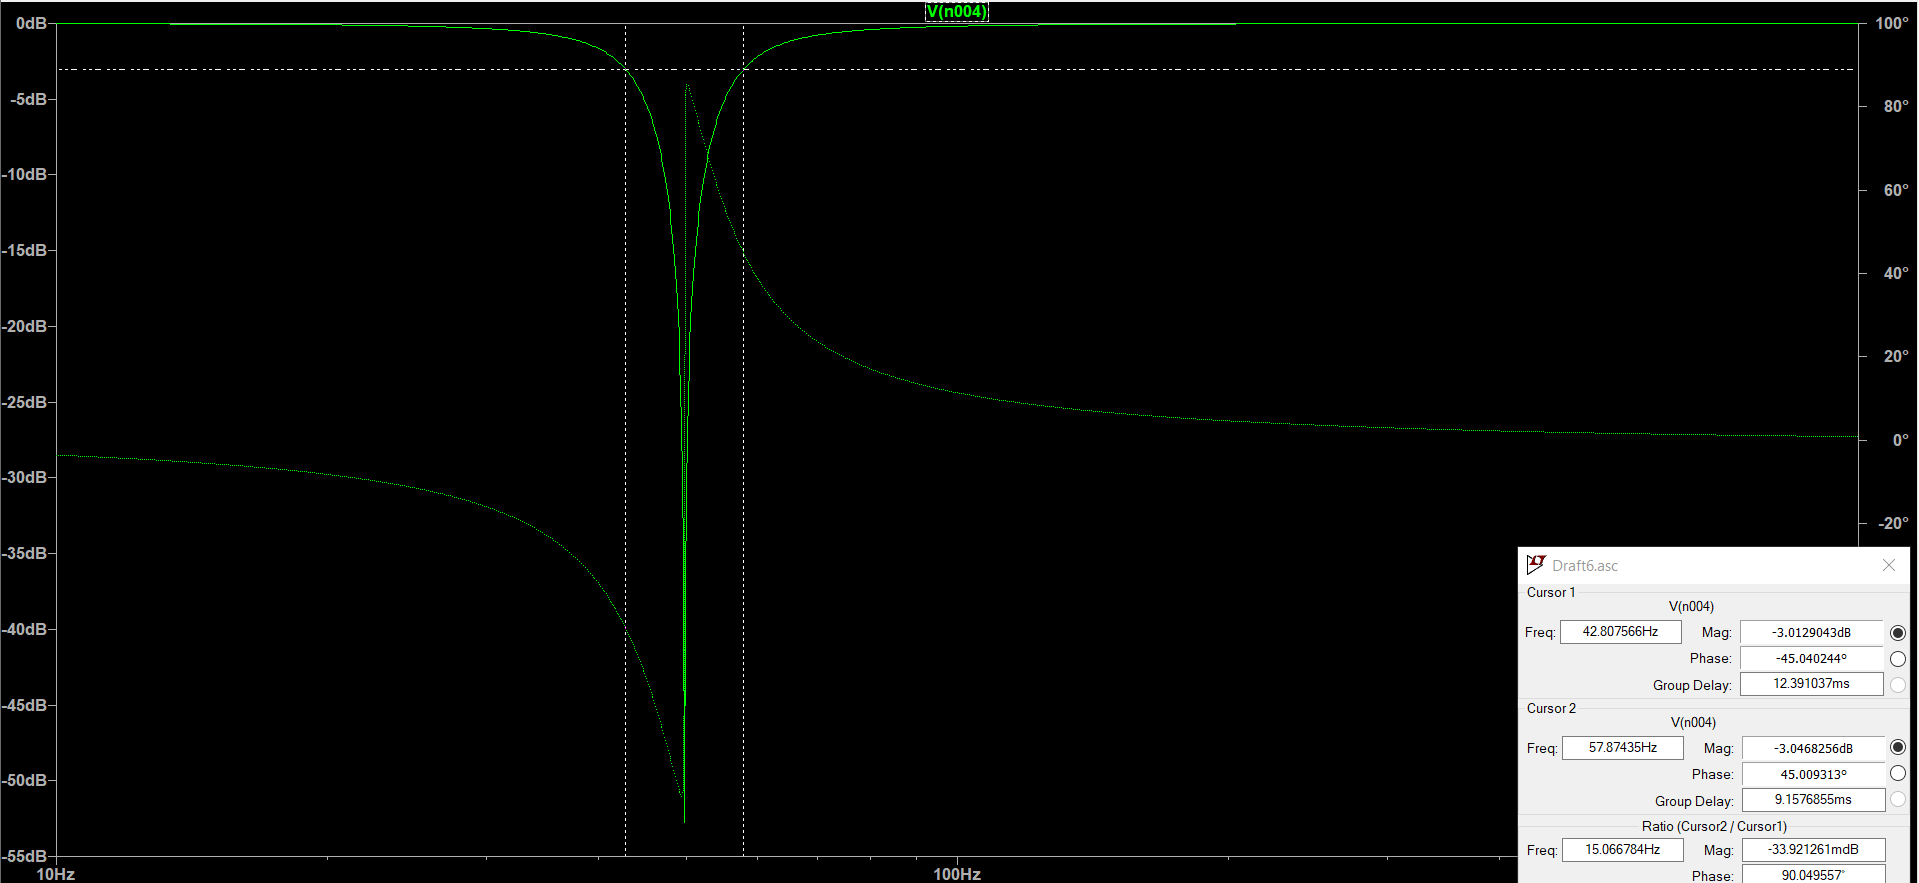

we set the tolerance to 2% and R3 to 82 and run the simulation. if 0.9 accuracy is achieved then it's possible, otherwise it's not.

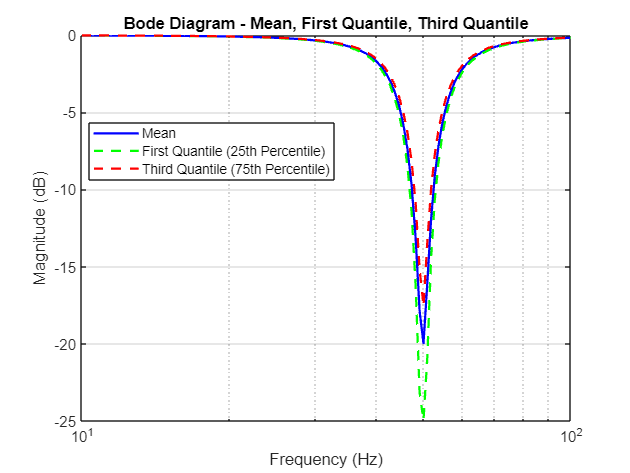

% Number of Monte Carlo iterations
numIterations = 2000;

% Frequency range for response plot (10 Hz to 100 kHz)
f = linspace(10, 100, 100);  % 100 points between 10 Hz and 100 Hz
omega = 2 * pi * f;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 82;   % 150 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

% Tolerance (2%)
tolerance = 0.02;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% Monte Carlo simulation
for i = 1:numIterations
    % Generate random values for resistors and capacitors using normrnd
    R1_rand = normrnd(R1_val, tolerance * R1_val);
    R2_rand = normrnd(R2_val, tolerance * R2_val);
    R3_rand = normrnd(R3_val, tolerance * R3_val);
    R4_rand = normrnd(R4_val, tolerance * R4_val);
    R5_rand = normrnd(R5_val, tolerance * R5_val);
    R6_rand = normrnd(R6_val, tolerance * R6_val);
    C1_rand = normrnd(C1_val, tolerance * C1_val);
    C2_rand = normrnd(C2_val, tolerance * C2_val);
    C3_rand = normrnd(C3_val, tolerance * C3_val);
    C4_rand = normrnd(C4_val, tolerance * C4_val);
    
    % Substitute all random values including constants R3 and R4
    H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
        [R1_rand, R2_rand, R3_val, R4_val, R5_rand, R6_rand, C1_rand, C2_rand, C3_rand, C4_rand]);
    
    % Convert symbolic transfer function to numeric function with s as the only variable
    H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
    
    % Compute magnitude response
    H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
end

% Compute mean, first quantile, and third quantile of H_mag_all
H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response
H_mag_first_quantile = quantile(H_mag_all, 0.25, 1);  % 25th percentile (first quantile)
H_mag_third_quantile = quantile(H_mag_all, 0.75, 1);  % 75th percentile (third quantile)

% Convert to decibels (dB)
H_mag_mean_dB = 20 * log10(H_mag_mean);
H_mag_first_quantile_dB = 20 * log10(H_mag_first_quantile);
H_mag_third_quantile_dB = 20 * log10(H_mag_third_quantile);

% Plot Bode diagram
figure;
semilogx(f, H_mag_mean_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, H_mag_first_quantile_dB, '--g', 'LineWidth', 1.5);
semilogx(f, H_mag_third_quantile_dB, '--r', 'LineWidth', 1.5);
grid on;

% Add labels, title, and legend
title('Bode Diagram - Mean, First Quantile, Third Quantile');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Mean', 'First Quantile (25th Percentile)', 'Third Quantile (75th Percentile)', 'Location', 'Best');
hold off;

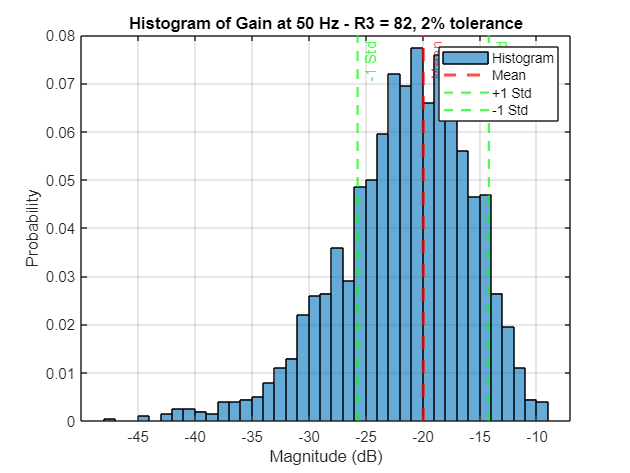

% Target frequency fo (Hz)
fo_target = 50.0;  % Target frequency is 49.8 Hz

% Find the closest index to fo_target in the frequency array
[~, fo_index] = min(abs(f - fo_target));

% Extract the mean magnitude response at fo
H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

% Extract all Monte Carlo responses at fo for histogram comparison
H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

% Compute standard deviation at fo
std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

% Plot the histogram of all Monte Carlo responses
figure;
histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
hold on;

% Plot a vertical line for the mean value
xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

% Plot vertical lines for ±1 standard deviation
xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

% Labels, title, and grid
xlabel('Magnitude (dB)');
ylabel('Probability');
title(['Histogram of Gain at ', num2str(fo_target), ' Hz - R3 = 82, 2% tolerance']);
grid on;
legend('Histogram', 'Mean', '+1 Std', '-1 Std');
hold off;

The graph shows a clear gap between the required 0.9 probability and the achieved performance, making it impractical to achieve both a high Q factor and a narrow bandwidth with these constraints.

## Robust Circuit Method

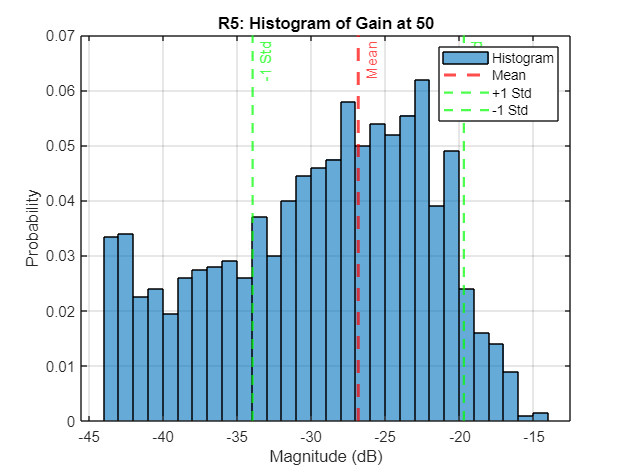

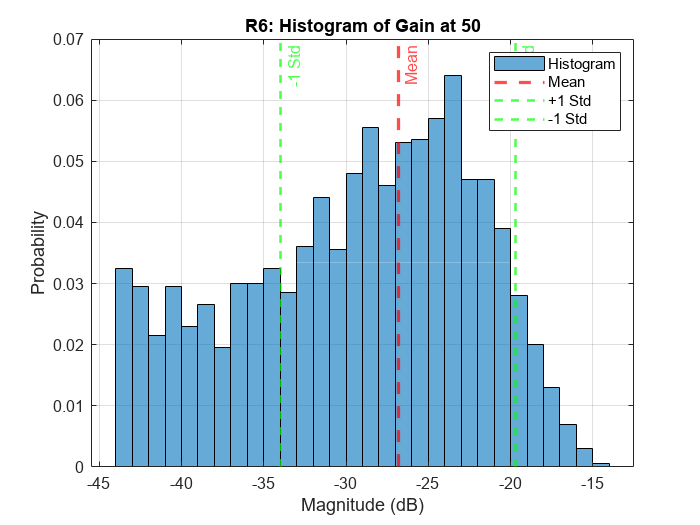

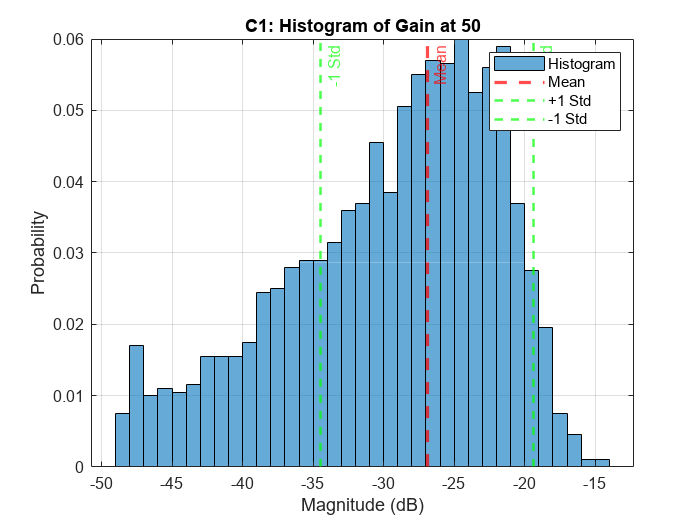

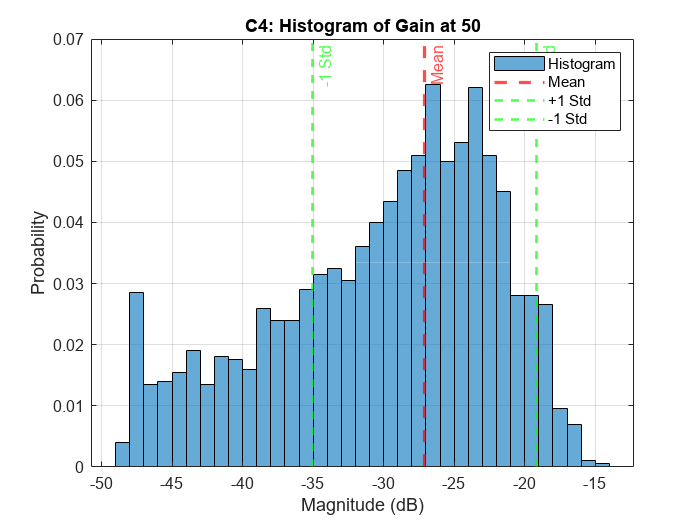

% Number of Monte Carlo iterations
numIterations = 2000;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 150;   % 150 Ohm (RQ1)
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

tolerance = 0.05;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% List of components to apply tolerance to
components = {'R5', 'R6', 'C1', 'C4'};

% Loop through each component and apply 5% tolerance
for k = 1:length(components)
    % Apply 5% tolerance to the current component, others remain ideal
    for i = 1:numIterations
        % Generate random values for the current component
        switch components{k}
            case 'R5'
                R5_rand = normrnd(R5_val/2, tolerance * R5_val/2) ...
                        + normrnd(R5_val/2, tolerance * R5_val/2);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_rand, R6_val, C1_val, C2_val, C3_val, C4_val]);
            case 'R6'
                R6_rand = normrnd(R6_val/2, tolerance * R6_val/2) ...
                        + normrnd(R6_val/2, tolerance * R6_val/2);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_rand, C1_val, C2_val, C3_val, C4_val]);
            case 'C1'
                C1_rand = normrnd(C1_val/2, tolerance * C1_val/2) ...
                        + normrnd(C1_val/2, tolerance * C1_val/2);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_rand, C2_val, C3_val, C4_val]);
            case 'C4'
                C4_rand = normrnd(C4_val/2, tolerance * C4_val/2) ...
                        + normrnd(C4_val/2, tolerance * C4_val/2);
                H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
                    [R1_val, R2_val, R3_val, R4_val, R5_val, R6_val, C1_val, C2_val, C3_val, C4_rand]);
        end
        
        % Convert symbolic transfer function to numeric function with s as the only variable
        H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
        
        % Compute magnitude response
        H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
    end

    % Compute mean, first quantile, and third quantile of H_mag_all
    H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response

    % Convert to decibels (dB)
    H_mag_mean_dB = 20 * log10(H_mag_mean);

    % Target frequency for fo (Hz)
    fo_target = 50.0;  % Target frequency is 49.8 Hz

    % Find the closest index to fo_target in the frequency array
    [~, fo_index] = min(abs(f - fo_target));

    % Extract the mean magnitude response at fo
    H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
    H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

    % Extract all Monte Carlo responses at fo for histogram comparison
    H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

    % Compute standard deviation at fo
    std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

    % Plot the histogram of all Monte Carlo responses
    figure;
    histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
    hold on;

    % Plot a vertical line for the mean value
    xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

    % Plot vertical lines for ±1 standard deviation
    xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
    xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

    % Labels, title, and grid
    xlabel('Magnitude (dB)');
    ylabel('Probability');
    title([num2str(components{k}), ': Histogram of Gain at ', num2str(fo_target)]);
    grid on;
    legend('Histogram', 'Mean', '+1 Std', '-1 Std');
    hold off;
end

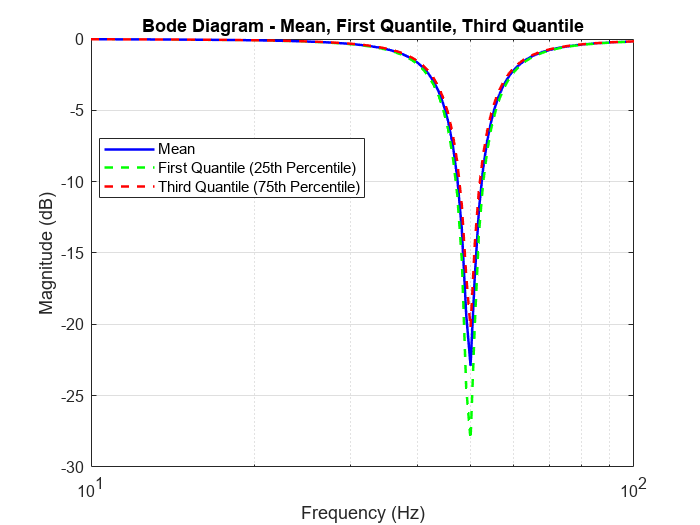

% Number of Monte Carlo iterations
numIterations = 2000;

% Frequency range for response plot (10 Hz to 100 kHz)
f = linspace(10, 100, 100);  % 100 points between 10 Hz and 100 Hz
omega = 2 * pi * f;

% Nominal values for resistors and capacitors
R1_val = 680e3; % 680 kOhm
R2_val = 680e3;
R3_val = 82;
R4_val = 1e3;  % 1 kOhm (RQ2)
R5_val = 680e3;
R6_val = 680e3;
C1_val = 4.7e-9; % 4.7 nF
C2_val = 4.7e-9;
C3_val = 4.7e-9;
C4_val = 4.7e-9;

tolerance = 0.02;

% Preallocate arrays for magnitude response
H_mag_all = zeros(numIterations, length(f));

% Monte Carlo simulation
for i = 1:numIterations
    % Generate random values for resistors and capacitors using normrnd
    R1_rand = normrnd(R1_val/2, tolerance * R1_val/2) + normrnd(R1_val/2, tolerance * R1_val/2);
    R2_rand = normrnd(R2_val/2, tolerance * R2_val/2) + normrnd(R2_val/2, tolerance * R2_val/2);
    R3_rand = normrnd(R3_val/2, tolerance * R3_val/2) + normrnd(R3_val/2, tolerance * R3_val/2);
    R4_rand = normrnd(R4_val/2, tolerance * R4_val/2) + normrnd(R4_val/2, tolerance * R4_val/2);
    R5_rand = normrnd(R5_val/2, tolerance * R5_val/2) + normrnd(R5_val/2, tolerance * R5_val/2);
    R6_rand = normrnd(R6_val/2, tolerance * R6_val/2) + normrnd(R6_val/2, tolerance * R6_val/2);
    C1_rand = normrnd(C1_val/2, tolerance * C1_val/2) + normrnd(C1_val/2, tolerance * C1_val/2);
    C2_rand = normrnd(C2_val/2, tolerance * C2_val/2) + normrnd(C2_val/2, tolerance * C2_val/2);
    C3_rand = normrnd(C3_val/2, tolerance * C3_val/2) + normrnd(C3_val/2, tolerance * C3_val/2);
    C4_rand = normrnd(C4_val/2, tolerance * C4_val/2) + normrnd(C4_val/2, tolerance * C4_val/2);
    
    
    % Substitute all random values including constants R3 and R4
    H_num_rand = subs(H_sol, [R1, R2, R3, R4, R5, R6, C1, C2, C3, C4], ...
        [R1_rand, R2_rand, R3_val, R4_val, R5_rand, R6_rand, C1_rand, C2_rand, C3_rand, C4_rand]);
    
    % Convert symbolic transfer function to numeric function with s as the only variable
    H_num_func_rand = matlabFunction(H_num_rand, 'Vars', s);
    
    % Compute magnitude response
    H_mag_all(i, :) = abs(H_num_func_rand(1j * omega));
end

% Compute mean, first quantile, and third quantile of H_mag_all
H_mag_mean = mean(H_mag_all, 1);  % Mean magnitude response
H_mag_first_quantile = quantile(H_mag_all, 0.25, 1);  % 25th percentile (first quantile)
H_mag_third_quantile = quantile(H_mag_all, 0.75, 1);  % 75th percentile (third quantile)

% Convert to decibels (dB)
H_mag_mean_dB = 20 * log10(H_mag_mean);
H_mag_first_quantile_dB = 20 * log10(H_mag_first_quantile);
H_mag_third_quantile_dB = 20 * log10(H_mag_third_quantile);

% Plot Bode diagram
figure;
semilogx(f, H_mag_mean_dB, 'b', 'LineWidth', 1.5); hold on;
semilogx(f, H_mag_first_quantile_dB, '--g', 'LineWidth', 1.5);
semilogx(f, H_mag_third_quantile_dB, '--r', 'LineWidth', 1.5);
grid on;

% Add labels, title, and legend
title('Bode Diagram - Mean, First Quantile, Third Quantile');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Mean', 'First Quantile (25th Percentile)', 'Third Quantile (75th Percentile)', 'Location', 'Best');
hold off;

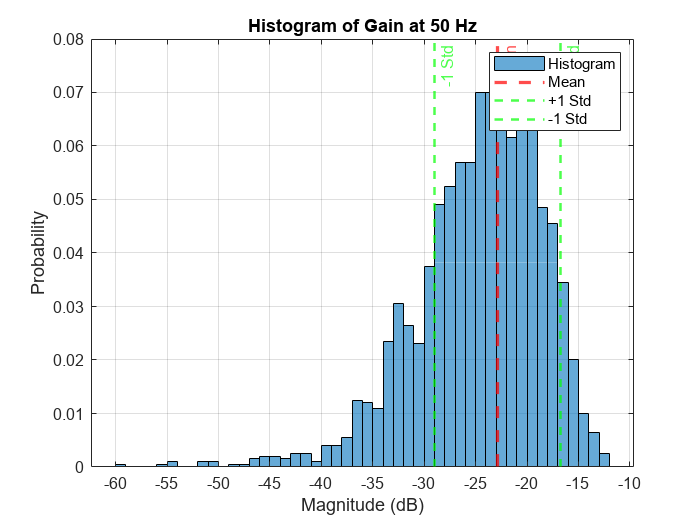


% Target frequency fo (Hz)
fo_target = 50.0;  % Target frequency is 49.8 Hz

% Find the closest index to fo_target in the frequency array
[~, fo_index] = min(abs(f - fo_target));

% Extract the mean magnitude response at fo
H_mean_at_fo = H_mag_mean(fo_index);  % Mean magnitude response (linear scale)
H_mean_at_fo_dB = 20 * log10(H_mean_at_fo);  % Convert mean to dB

% Extract all Monte Carlo responses at fo for histogram comparison
H_all_at_fo_dB = 20 * log10(H_mag_all(:, fo_index));  % Convert all Monte Carlo magnitudes to dB

% Compute standard deviation at fo
std_gain_at_fo = std(H_all_at_fo_dB);  % Standard deviation in dB

% Plot the histogram of all Monte Carlo responses
figure;
histogram(H_all_at_fo_dB, 'Normalization', 'probability', 'BinWidth', 1);  % Normalize to probability
hold on;

% Plot a vertical line for the mean value
xline(H_mean_at_fo_dB, '--r', 'LineWidth', 2, 'Label', 'Mean');

% Plot vertical lines for ±1 standard deviation
xline(H_mean_at_fo_dB + std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '+1 Std');
xline(H_mean_at_fo_dB - std_gain_at_fo, '--g', 'LineWidth', 1.5, 'Label', '-1 Std');

% Labels, title, and grid
xlabel('Magnitude (dB)');
ylabel('Probability');
title(['Histogram of Gain at ', num2str(fo_target), ' Hz']);
grid on;
legend('Histogram', 'Mean', '+1 Std', '-1 Std');
hold off;